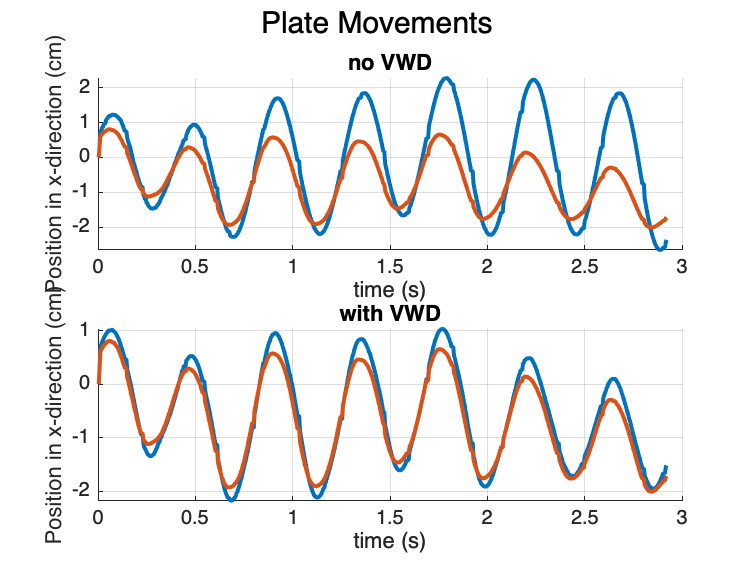

clear, clc, close all
load x3
load s3

time= [1:length(xReal)]/240;
tPause= 3/length(xReal);

for i= 1:5:length(xReal)
    clf
    figure(1), sgtitle("Plate Movements")
    subplot(2, 1, 1), hold on
    plot(time(1:i), xReal(4, 1:i)-xReal(4, 1), DisplayName= "Upper Plate", LineWidth= 2)
    plot(time(1:i), xReal(5, 1:i)-xReal(5, 1), DisplayName= "Ground", LineWidth= 2)
    xlabel("time (s)"), ylabel("Position in x-direction (cm)"), grid
    title("no VWD")
    
    subplot(2, 1, 2), hold on
    plot(time(1:i), xReal(1, 1:i)-xReal(1, 1), DisplayName= "Upper Plate", LineWidth= 2)
    plot(time(1:i), xReal(5, 1:i)-xReal(5, 1), DisplayName= "Ground", LineWidth= 2)
    xlabel("time (s)"), ylabel("Position in x-direction (cm)"), grid
    title("with VWD")
    pause(0)
end


    figure(2), sgtitle("Interstory Drift")
    subplot(2, 1, 1), hold on
    plot(time, [xReal(4, i)-xReal(4, 1)]-[xReal(5, i)-xReal(5, 1)], Color= "#7E2F8E", LineWidth= 2)
    xlabel("time (s)"), ylabel("Column deflection (cm)"), grid
    title("no VWD"), a= axis;
    
    subplot(2, 1, 2), hold on
    plot(time, [xReal(1, i)-xReal(1, 1)]-[xReal(5, i)-xReal(5, 1)], Color= "#7E2F8E", LineWidth= 2)
    xlabel("time (s)"), ylabel("Column deflection (cm)"), grid
    title("with VWD"), axis(a)
    pause(tPause)